# Solution to the *Human Activity Recognition* exercise

## 1. Load data

Load the data in `HAData.mat`.

load HAData

This file contains a table, `data`, with 44 columns, containing sensor information for experimental participants performing 6 different activities. The second column, `Activity`, contains a label for the activity being performed. Note that the data is already normalized.

## 2. Extract variables of interest

Extract the sensor data (exclude the first two columns) from the table into a new table, `measurements`. Extract the `Activity` as the response variable.

measurements = data(:,3:end);
activity = data.Activity;

## 3. Partition data

Partition the data into 70% training and 30% validation sets. 

pt = cvpartition(activity,'holdout',0.3); 
xTrain = measurements(training(pt),:);
yTrain = activity(training(pt));
xValid = measurements(test(pt),:);
yValid = activity(test(pt));

## 4. Fit classification tree

Fit a predictive model of a classification tree with training data.  

t = fitctree(xTrain,yTrain);

Visualize tree

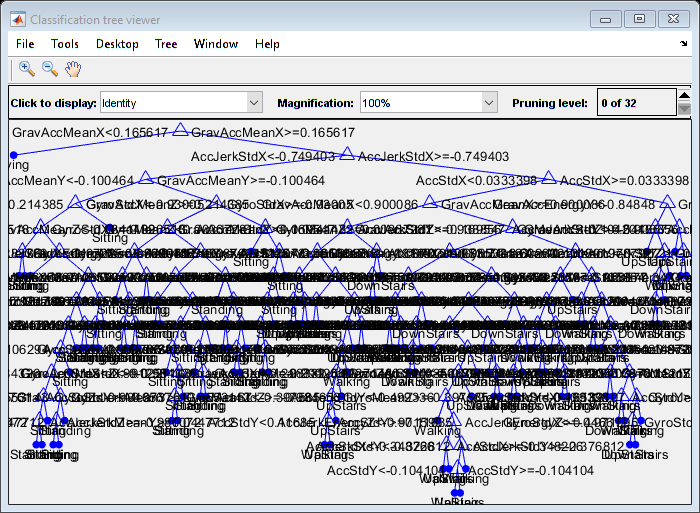

view(t,'Mode','graph')

## 5. Predict and evaluate quality

Based on this model, predict the activity using the validation set.

yPred = predict(t,xValid);

trainingErr = 100*resubLoss(t)  

trainingErr = 1.5782

validErr = 100*loss(t,xValid,yValid)

validErr = 7.5558

## 6. Visualize accuracy of predictions with confusion matrix

Evaluate the classification by constructing a confusion matrix and visualize the groupings.

[c,grps] = confusionmat(yValid,yPred)

c =    220     8    14     0     0     0
    24   180    11     0     0     0
     9     5   160     0     0     0
     0     0     0   265    20     0
     0     0     0    28   296     0
     0     0     0     0     0   335


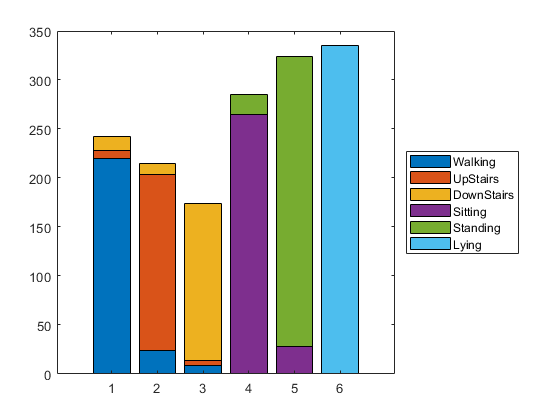


bar(c,'stacked')
legend(categories(grps),'Location','EastOutside')

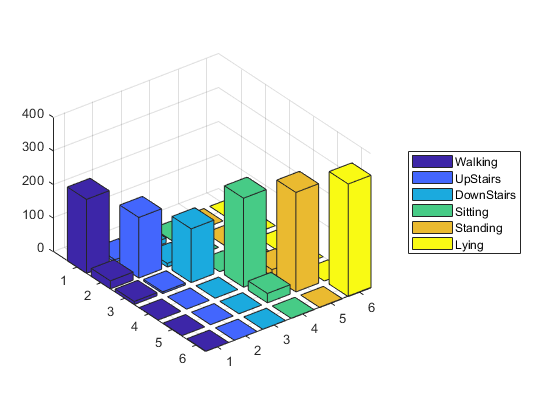


bar3(c)
legend(categories(grps),'Location','EastOutside')